Calculation of population of NV- center under zero-field (B = 0), using equation (11) from [http://arxiv.org/abs/2104.00744](http://arxiv.org/abs/2104.00744)

#### The parameters

Obtained from Robledo, L., Bernien, H., Sar, T. Van Der, & Hanson, R. (2011). Spin dynamics in the optical cycle of single nitrogen-vacancy centres in diamond. *New Journal of Physics*, *13*(2), 25013–25024. https://doi.org/10.1088/1367-2630/13/2/025013

clear 
clc
close all

K0 = zeros(7,7);
 
beta = 0.03;
k0_r = 63;
k0_47 = 13;
k0_57 = 80;
k0_71 = 3.5;
k0_72 = 2.2;
K0(1,4) = beta*k0_r;
K0(2,5) = beta*k0_r;
K0(3,6) = beta*k0_r;
K0(4,1) = k0_r;
K0(5,2) = k0_r;
K0(6,3) = k0_r;
K0(4,7) = k0_47;
K0(5,7) = k0_57;
K0(6,7) = k0_57;
K0(7,1) = k0_71;
K0(7,2) = k0_72;
K0(7,3) = k0_72;
disp(K0)

         0         0         0    1.8900         0         0         0
         0         0         0         0    1.8900         0         0
         0         0         0         0         0    1.8900         0
   63.0000         0         0         0         0         0   13.0000
         0   63.0000         0         0         0         0   80.0000
         0         0   63.0000         0         0         0   80.0000
    3.5000    2.2000    2.2000         0         0         0         0



### The rate equations

code provided by Professor Takahashi

K = K0;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

## Solving the system numerically

### Initial conditions

cond1 = 1/3;
cond2 = 1/3;
cond3 = 1/3;
cond4 = 0;
cond5 = 0;
cond6 = 0;
cond7 = 0;
conds = [cond1; cond2; cond3; cond4; cond5; cond6; cond7];

### Using ode45 to solve the equations

[t, n_res] = ode45(odes, [0:5e-3:20000e-3], conds);

## Plotting

### Plotting only n1, n2, and n3

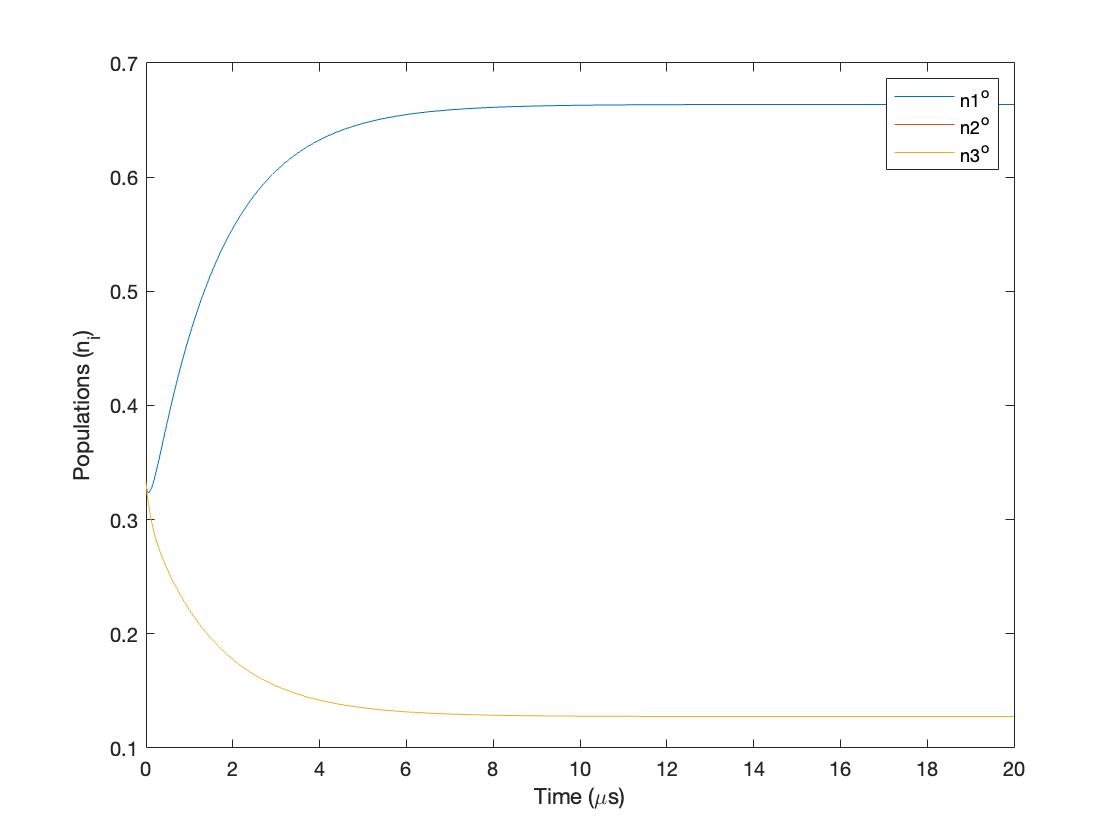

% figure; plot(sol.x,sol.y)
% legend
plot(t, n_res(:,1));
hold on;
plot(t, n_res(:,2));
hold on;
plot(t, n_res(:, 3));
hold off;
xlim([0 20]);
xlabel('Time (\mus)');
ylabel("Populations (n_i)");
legend("n1^o", "n2^o", "n3^o");

#### Plotting all the populations

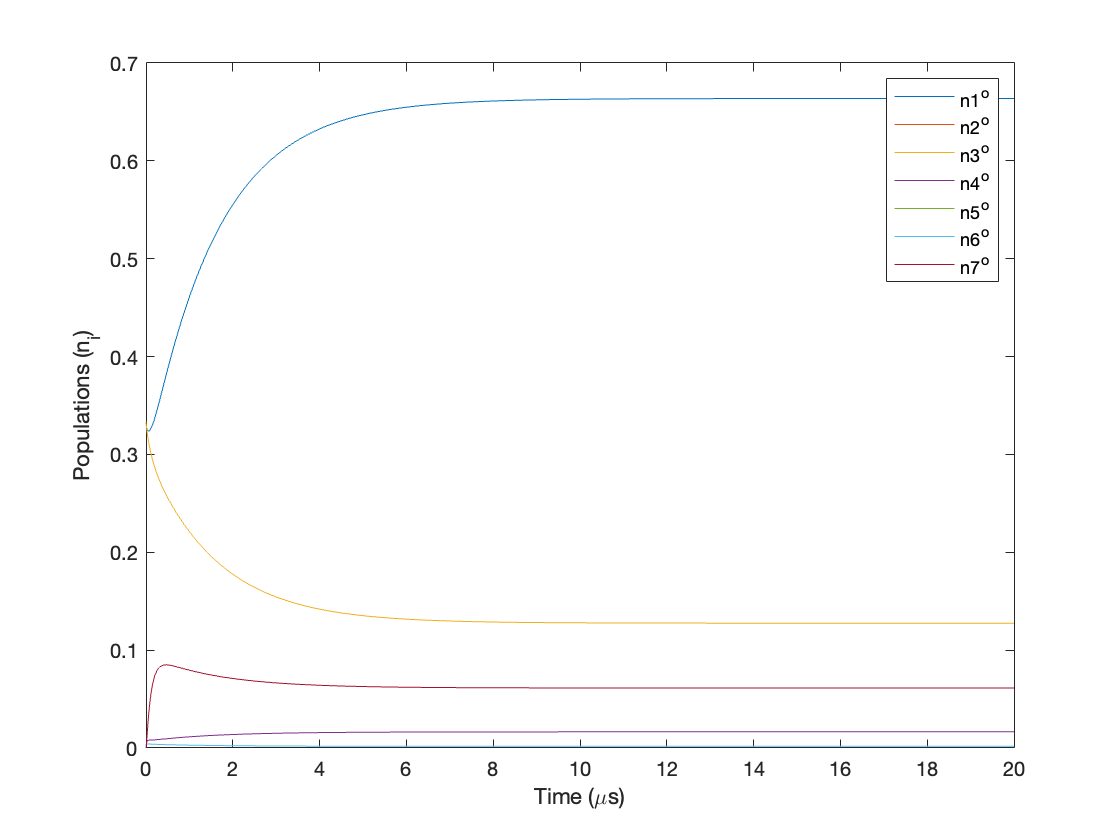

plot(t, n_res);
% xlim([0 20]);
xlabel('Time (\mus)');
ylabel("Populations (n_i)");
legend("n1^o", "n2^o", "n3^o", "n4^o", "n5^o", "n6^o", "n7^o");

save('NV_population_data.mat')

## Solving the system analytically (ignore this part)

### Initial conditions

% cond1 = n01(0) == 1/3;
% cond2 = n02(0) == 1/3;
% cond3 = n03(0) == 1/3;
% cond4 = n04(0) == 0;
% cond5 = n05(0) == 0;
% cond6 = n06(0) == 0;
% cond7 = n07(0) == 0;
% conds = [cond1; cond2; cond3; cond4; cond5; cond6; cond7];

% sol = dsolve(odes, conds)
% disp(sol.n01)

% fplot(sol.n01)  % was able to obtain analytical solutions, but plotting takes too long (5+ minutes)

function sum = NV_sum(i, K0, n0)
%     syms sum(t);
    sum = 0;
    for j = 1 : 7
        sum = sum + (K0(j,i) * n0(j) - K0(i,j) * n0(i));
    end
end

